# mAD test

## small tile

run_id = 'test';

input_path = 'F:/2020-09-14-mAD/AD_mouse9735/';
useGPU = true;


data_dirs = dir(fullfile(input_path, "round1", "tile_*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name)
data_dirs = data_dirs(2:2)

Ndirs = numel(data_dirs);


tic;
for p=1:Ndirs
    
    curr_data_dir = data_dirs{p};
    curr_out_path = fullfile(input_path, 'output', run_id, curr_data_dir)

    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
                
    sdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
    sdata.log = fopen(fullfile(curr_out_path, 'log.txt'), 'w');
    sdata = sdata.LoadRawImages('sub_dir', curr_data_dir, 'input_dim', [3072 3072 31 4 8]);
    sdata.rawImages = sdata.rawImages(768:1791, 2001:3024, :,:,:);
    sdata = sdata.SwapChannels; % !!
%     sdata = sdata.HistEqualize('Method', "inter_round");
%     sdata = sdata.HistEqualize('Method', "intra_round");
    sdata = sdata.MorphoRecon('Method', "2d", 'radius', 3);
    
    sdata = sdata.test_GlobalRegistration;
    sdata.registeredImages = gpuArray(sdata.registeredImages);
    sdata = sdata.LocalRegistration('Iterations', 50, 'AccumulatedFieldSmoothing', 1);
    
end
toc
% fclose(sdata.log)

## Spot Finding test

sdata = sdata.LoadCodebook('remove_index', 5);
sdata = sdata.SpotFinding('Method', "max3d", 'qualityThreshold', 0.01, ...
        'volumeThreshold', 1, 'barcodeMethod', "iteration", 'showPlots', true);
sdata = sdata.ReadsExtraction('showPlots', false, 'voxelSize', [2 2 1]); 
sdata = sdata.ReadsFiltration('mode', "duo", 'endBases', ['C', 'T'], 'showPlots', false);

img = new_LoadMultipageTiff(fullfile('F:/2020-09-14-mAD/AD_mouse9735/output/max/pi/tile_2.tif'), 'uint8', 'uint8', false);
% img = max(sdata.registeredImages(:,:,:,:,1), [], 4);
img = max(img, [], 3);
img = img(768:1791, 2001:3024);
plot_centroids(sdata.goodSpots, img, 3)

## Whole tile test

run_id = 'rd8_dots_he_mr';

% input_path = 'F:/2020-09-14-mAD/AD_mouse9723/';
% input_dim = [3072 3072 30 4 8];
% gpu_block = [1024 1024 30 4 8];

input_path = 'F:/2020-09-14-mAD/AD_mouse9735/';
input_dim = [3072 3072 31 4 8];
gpu_block = [1024 1024 31 4 8];

useGPU = true;

data_dirs = dir(fullfile(input_path, "round1", "tile_*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name);
data_dirs = data_dirs(2:2)

data_dirs = 1×1 cell array
    {'tile_2'}



Ndirs = numel(data_dirs);
upd = textprogressbar(Ndirs, 'updatestep', 1);

Completed [                    ]   0% --:--:--



all_goodSpots = [];
all_goodReads = [];
all_score = [];
all_counts = 0;
    
starting = tic;
for p=1:Ndirs
    
    
    curr_data_dir = data_dirs{p};
    curr_out_path = fullfile(input_path, 'output', run_id, curr_data_dir)
    
    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
                
    sdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
    sdata.log = fopen(fullfile(curr_out_path, 'log.txt'), 'w');
    fprintf(sdata.log, sprintf("====Current Tile: %s====\n", curr_data_dir));
    sdata = sdata.LoadRawImages('sub_dir', curr_data_dir, 'input_dim', input_dim);
    sdata = sdata.SwapChannels; % !!
    
%     cell_imgs = RegisterCellImage(sdata, input_path, 'protein', curr_data_dir);

%     ref_img = new_LoadMultipageTiff(fullfile('F:/2020-09-14-mAD/AD_mouse9723/round1/tile_1/9723seqA1_TileScan_001_Tile 1_cmle_ch00.tif'), 'uint8', 'uint8', false);
%     for r=1:sdata.Nround
%         for c=1:sdata.Nchannel
%             sdata.rawImages(:,:,:,c,r) = uint8(imhistmatchn(uint8(sdata.rawImages(:,:,:,c,r)), ref_img, 256));
%         end
%     end

    sdata = sdata.HistEqualize('Method', "inter_round");
    sdata = sdata.HistEqualize('Method', "intra_round");
    sdata = sdata.MorphoRecon('Method', "2d", 'radius', 3);
    
    sdata = sdata.test_GlobalRegistration;

    gpu_overlap = 0;
    gb_idx = BlockTest(sdata.rawImages, gpu_block, gpu_overlap);
    NgpuBlock = numel(gb_idx)
    
    tile_allSpots = [];
    tile_goodSpots = [];
    tile_goodReads = [];
    tile_score = [];
    tile_counts = 0;
    
    for i =1:NgpuBlock
        
        bdata_start = tic;
        gpu_idx = gb_idx{i}
        
        fprintf(sdata.log, sprintf("====Current Block: %d====\n", i));
        fprintf(sdata.log, sprintf("Index: %d - %d - %d - %d\n", gpu_idx));
        
        bdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
        bdata.log = sdata.log;
        bdata = bdata.LoadDim(gpu_block);
        bdata.registeredImages = gpuArray(sdata.registeredImages(...
            gpu_idx(1,1):gpu_idx(1,2),...
            gpu_idx(2,1):gpu_idx(2,2),...
            :,:,:));
        
        bdata = bdata.LocalRegistration('Iterations', 50, 'AccumulatedFieldSmoothing', 1);
         
        % replace the old image 
        sdata.registeredImages(...
            gpu_idx(1,1):gpu_idx(1,2),...
            gpu_idx(2,1):gpu_idx(2,2),...
            :,:,:) = bdata.registeredImages;
        
        bdata = bdata.LoadCodebook('remove_index', 5);
        bdata = bdata.SpotFinding('Method', "max3d", 'ref_index', 8, 'qualityThreshold', 0.01, ...
                'volumeThreshold', 15, 'barcodeMethod', "iteration", 'showPlots', false);
        bdata = bdata.ReadsExtraction('showPlots', false, 'voxelSize', [2 2 1]); 
        bdata = bdata.ReadsFiltration('mode', "duo", 'endBases', ['C', 'T'], 'showPlots', false);
        
        block_offsets = [gpu_idx(2,1) - 1 gpu_idx(1,1) - 1 0]
        if size(bdata.goodSpots, 1) ~= 0
            g_block_offsets = repmat(block_offsets, size(bdata.goodSpots, 1), 1);
            bdata.goodSpots = bdata.goodSpots + int16(g_block_offsets);
            
            a_block_offsets = repmat(block_offsets, size(bdata.allSpots, 1), 1);
            bdata.allSpots = bdata.allSpots + int16(a_block_offsets);
        end
        
        % Update tile reads
        tile_allSpots = [tile_allSpots; bdata.allSpots];
        tile_goodSpots = [tile_goodSpots; bdata.goodSpots];
        tile_goodReads = [tile_goodReads; bdata.goodReads];
        tile_score = [tile_score; bdata.FilterScores];
        tile_counts = tile_counts + size(bdata.allSpots, 1);
        
        fprintf(sprintf("====Block %d Finished [time=%02f]====", i, toc(bdata_start)));
    end
    
%     % Save registered image
%     output_dir = fullfile(curr_out_path, 'registered_image');
%     if ~exist(output_dir, 'dir')
%        mkdir(output_dir);
%     end
%     new_SaveImg(output_dir, sdata.registeredImages);
%     
%     % Save cell image
%     output_dir = fullfile(input_path, 'output', run_id);
%     % output_dir = fullfile(curr_out_path, 'registered_cell_image');
%     if ~exist(output_dir, 'dir')
%        mkdir(output_dir);
%     end
%     SaveCellImg(output_dir, cell_imgs, curr_data_dir);
    
    % Save tile points 
    save(fullfile(curr_out_path, strcat('goodPoints_max3d.mat')), 'tile_goodReads', 'tile_goodSpots', 'tile_allSpots');
    
    
    all_score = [all_score; tile_score];
    all_counts = all_counts + tile_counts;
    fprintf(sdata.log, sprintf("Average Score: %.2f - %.2f - %.2f\n", mean(tile_score, 'omitnan')));
    
    reset(gpuDevice)
    
    fclose(sdata.log);
    upd(p);
end

curr_out_path = 'F:\2020-09-14-mAD\AD_mouse9735\output\rd8_dots_he_mr\tile_2'

Pipeline Obj is generated...


====Loading raw images====
Loading round 1...[time = 22.47 s]
Loading round 2...[time = 22.46 s]
Loading round 3...[time = 17.46 s]
Loading round 4...[time = 17.42 s]
Loading round 5...[time = 17.30 s]
Loading round 6...[time = 17.39 s]
Loading round 7...[time = 17.71 s]
Loading round 8...[time = 22.60 s]
Raw image as 5-D array


====Swap Channels====
Channel 2 <==> Channel 3


====Histogram Equalization====
Method: inter_round
Equalizing channel 1
Equalizing channel 2
Equalizing channel 3
Equalizing channel 4


====Histogram Equalization====
Method: intra_round
Equalizing round 1
Equalizing round 2
Equalizing round 3
Equalizing round 4
Equalizing round 5
Equalizing round 6
Equalizing round 7
Equalizing round 8


====Morphological Reconstruction====
Method: 2d
Processing Round 1...[time = 11.65 s]
Processing Round 2...[time = 5.12 s]
Processing Round 3...[time = 4.96 s]
Processing Round 4...[time = 4.91 s]
Processing Round 5...[time = 5.12 s]
Processing Round 6...[time = 4.87 s]
Processing Round 7...[time = 4.96 s]
Processing Round 8...[time = 4.90 s]


====Global Registration====
Round 2 vs. Round 1 finished [time=44.518048]
Shifted by 5  2  1
Round 3 vs. Round 1 finished [time=43.845436]
Shifted by 3  3  7
Round 4 vs. Round 1 finished [time=43.833808]
Shifted by 5  5  7
Round 5 vs. Round 1 finished [time=43.902145]
Shifted by -2  4  5
Round 6 vs. Round 1 finished [time=44.366040]
Shifted by -1  4  8
Round 7 vs. Round 1 finished [time=44.033040]
Shifted by 1  3  6
Round 8 vs. Round 1 finished [time=43.707702]
Shifted by 6  0  1


NgpuBlock = 9

gpu_idx =            1        1024
           1        1024


Pipeline Obj is generated...


====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 26.11 s]
Round 3 vs. Round 1...[time = 25.37 s]
Round 4 vs. Round 1...[time = 25.35 s]
Round 5 vs. Round 1...[time = 25.29 s]
Round 6 vs. Round 1...[time = 25.23 s]
Round 7 vs. Round 1...[time = 25.67 s]
Round 8 vs. Round 1...[time = 25.17 s]


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: max3d
Reference round: 8
Number of spots found by max3d: 41029
[time = 27.79 s]


====Reads Extraction====
voxel size: 2 x 2 x 1
Geting color sequence for each voxel...

Geting max color...
6316 
Decoding...
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).

0.846060 [34713 / 41029] percent of reads are below score thresh


====Reads Filtration====
mode: duo
Base in both ends: C --- T
Filtration Statistics:
0.519344 [18028 / 34713] percent of good reads match barcode pattern CN..NC - TN..NT
0.511077 [17741 / 34713] percent of good reads are in codebook
0.984080 [17741 / 18028] percent of form matched reads are in codebook


block_offsets =      0     0     0


====Block 1 Finished [time=241.242909]====

gpu_idx =            1        1024
        1025        2048


Pipeline Obj is generated...


====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 25.12 s]
Round 3 vs. Round 1...[time = 25.44 s]
Round 4 vs. Round 1...[time = 25.24 s]
Round 5 vs. Round 1...[time = 25.06 s]
Round 6 vs. Round 1...[time = 25.30 s]
Round 7 vs. Round 1...[time = 25.56 s]
Round 8 vs. Round 1...[time = 25.38 s]


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: max3d
Reference round: 8
Number of spots found by max3d: 75419
[time = 29.01 s]


====Reads Extraction====
voxel size: 2 x 2 x 1
Geting color sequence for each voxel...

Geting max color...
12922 
Decoding...

0.828664 [62497 / 75419] percent of reads are below score thresh


====Reads Filtration====
mode: duo
Base in both ends: C --- T
Filtration Statistics:
0.308095 [19255 / 62497] percent of good reads match barcode pattern CN..NC - TN..NT
0.297230 [18576 / 62497] percent of good reads are in codebook
0.964736 [18576 / 19255] percent of form matched reads are in codebook


block_offsets =         1024           0           0


====Block 2 Finished [time=236.716811]====

gpu_idx =            1        1024
        2049        3072


Pipeline Obj is generated...


====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 25.11 s]
Round 3 vs. Round 1...[time = 25.41 s]
Round 4 vs. Round 1...[time = 25.31 s]
Round 5 vs. Round 1...[time = 25.47 s]
Round 6 vs. Round 1...[time = 25.24 s]
Round 7 vs. Round 1...[time = 25.35 s]
Round 8 vs. Round 1...[time = 25.46 s]


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: max3d
Reference round: 8
Number of spots found by max3d: 73684
[time = 29.42 s]


====Reads Extraction====
voxel size: 2 x 2 x 1
Geting color sequence for each voxel...

Geting max color...
9216 
Decoding...

0.874925 [64468 / 73684] percent of reads are below score thresh


====Reads Filtration====
mode: duo
Base in both ends: C --- T
Filtration Statistics:
0.272492 [17567 / 64468] percent of good reads match barcode pattern CN..NC - TN..NT
0.260672 [16805 / 64468] percent of good reads are in codebook
0.956623 [16805 / 17567] percent of form matched reads are in codebook


block_offsets =         2048           0           0


====Block 3 Finished [time=237.485190]====

gpu_idx =         1025        2048
           1        1024


Pipeline Obj is generated...


====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 25.23 s]
Round 3 vs. Round 1...[time = 25.41 s]
Round 4 vs. Round 1...[time = 25.18 s]
Round 5 vs. Round 1...[time = 25.48 s]
Round 6 vs. Round 1...[time = 25.39 s]
Round 7 vs. Round 1...[time = 25.29 s]
Round 8 vs. Round 1...[time = 25.16 s]


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: max3d
Reference round: 8
Number of spots found by max3d: 35664
[time = 28.69 s]


====Reads Extraction====
voxel size: 2 x 2 x 1
Geting color sequence for each voxel...

Geting max color...
5288 
Decoding...

0.851727 [30376 / 35664] percent of reads are below score thresh


====Reads Filtration====
mode: duo
Base in both ends: C --- T
Filtration Statistics:
0.545431 [16568 / 30376] percent of good reads match barcode pattern CN..NC - TN..NT
0.538781 [16366 / 30376] percent of good reads are in codebook
0.987808 [16366 / 16568] percent of form matched reads are in codebook


block_offsets =            0        1024           0


====Block 4 Finished [time=223.707062]====

gpu_idx =         1025        2048
        1025        2048


Pipeline Obj is generated...


====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 25.40 s]
Round 3 vs. Round 1...[time = 25.17 s]
Round 4 vs. Round 1...[time = 25.53 s]
Round 5 vs. Round 1...[time = 25.30 s]
Round 6 vs. Round 1...[time = 25.41 s]
Round 7 vs. Round 1...[time = 25.38 s]
Round 8 vs. Round 1...[time = 25.40 s]


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: max3d
Reference round: 8
Number of spots found by max3d: 54130
[time = 28.51 s]


====Reads Extraction====
voxel size: 2 x 2 x 1
Geting color sequence for each voxel...

Geting max color...
8036 
Decoding...

0.851543 [46094 / 54130] percent of reads are below score thresh


====Reads Filtration====
mode: duo
Base in both ends: C --- T
Filtration Statistics:
0.485660 [22386 / 46094] percent of good reads match barcode pattern CN..NC - TN..NT
0.477806 [22024 / 46094] percent of good reads are in codebook
0.983829 [22024 / 22386] percent of form matched reads are in codebook


block_offsets =         1024        1024           0


====Block 5 Finished [time=230.191485]====

gpu_idx =         1025        2048
        2049        3072


Pipeline Obj is generated...


====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 25.23 s]
Round 3 vs. Round 1...[time = 25.46 s]
Round 4 vs. Round 1...[time = 24.06 s]
Round 5 vs. Round 1...[time = 23.76 s]
Round 6 vs. Round 1...[time = 24.09 s]
Round 7 vs. Round 1...[time = 24.24 s]
Round 8 vs. Round 1...[time = 23.84 s]


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: max3d
Reference round: 8
Number of spots found by max3d: 90215
[time = 26.39 s]


====Reads Extraction====
voxel size: 2 x 2 x 1
Geting color sequence for each voxel...

Geting max color...
16730 
Decoding...

0.814554 [73485 / 90215] percent of reads are below score thresh


====Reads Filtration====
mode: duo
Base in both ends: C --- T
Filtration Statistics:
0.224536 [16500 / 73485] percent of good reads match barcode pattern CN..NC - TN..NT
0.212901 [15645 / 73485] percent of good reads are in codebook
0.948182 [15645 / 16500] percent of form matched reads are in codebook


block_offsets =         2048        1024           0


====Block 6 Finished [time=228.336636]====

gpu_idx =         2049        3072
           1        1024


Pipeline Obj is generated...


====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 23.74 s]
Round 3 vs. Round 1...[time = 24.17 s]
Round 4 vs. Round 1...[time = 23.92 s]
Round 5 vs. Round 1...[time = 23.88 s]
Round 6 vs. Round 1...[time = 24.02 s]
Round 7 vs. Round 1...[time = 23.92 s]
Round 8 vs. Round 1...[time = 23.99 s]


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: max3d
Reference round: 8
Number of spots found by max3d: 32554
[time = 24.34 s]


====Reads Extraction====
voxel size: 2 x 2 x 1
Geting color sequence for each voxel...

Geting max color...
4334 
Decoding...

0.866867 [28220 / 32554] percent of reads are below score thresh


====Reads Filtration====
mode: duo
Base in both ends: C --- T
Filtration Statistics:
0.528774 [14922 / 28220] percent of good reads match barcode pattern CN..NC - TN..NT
0.520659 [14693 / 28220] percent of good reads are in codebook
0.984654 [14693 / 14922] percent of form matched reads are in codebook


block_offsets =            0        2048           0


====Block 7 Finished [time=206.702501]====

gpu_idx =         2049        3072
        1025        2048


Pipeline Obj is generated...


====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 23.53 s]
Round 3 vs. Round 1...[time = 23.57 s]
Round 4 vs. Round 1...[time = 23.67 s]
Round 5 vs. Round 1...[time = 23.84 s]
Round 6 vs. Round 1...[time = 23.71 s]
Round 7 vs. Round 1...[time = 24.04 s]
Round 8 vs. Round 1...[time = 23.74 s]


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: max3d
Reference round: 8
Number of spots found by max3d: 45875
[time = 24.86 s]


====Reads Extraction====
voxel size: 2 x 2 x 1
Geting color sequence for each voxel...

Geting max color...
6957 
Decoding...

0.848349 [38918 / 45875] percent of reads are below score thresh


====Reads Filtration====
mode: duo
Base in both ends: C --- T
Filtration Statistics:
0.502287 [19548 / 38918] percent of good reads match barcode pattern CN..NC - TN..NT
0.493885 [19221 / 38918] percent of good reads are in codebook
0.983272 [19221 / 19548] percent of form matched reads are in codebook


block_offsets =         1024        2048           0


====Block 8 Finished [time=210.159021]====

gpu_idx =         2049        3072
        2049        3072


Pipeline Obj is generated...


====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 23.91 s]
Round 3 vs. Round 1...[time = 23.69 s]
Round 4 vs. Round 1...[time = 23.86 s]
Round 5 vs. Round 1...[time = 23.67 s]
Round 6 vs. Round 1...[time = 23.70 s]
Round 7 vs. Round 1...[time = 23.80 s]
Round 8 vs. Round 1...[time = 23.64 s]


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: max3d
Reference round: 8
Number of spots found by max3d: 63997
[time = 26.19 s]


====Reads Extraction====
voxel size: 2 x 2 x 1
Geting color sequence for each voxel...

Geting max color...
9351 
Decoding...

0.853884 [54646 / 63997] percent of reads are below score thresh


====Reads Filtration====
mode: duo
Base in both ends: C --- T
Filtration Statistics:
0.384310 [21001 / 54646] percent of good reads match barcode pattern CN..NC - TN..NT
0.373861 [20430 / 54646] percent of good reads are in codebook
0.972811 [20430 / 21001] percent of form matched reads are in codebook


block_offsets =         2048        2048           0


====Block 9 Finished [time=217.607876]====

Completed [====================] Done. [2683 seconds]



sdata.jobFinished

ans = struct with fields:
                  LoadRawImages: 'uint8'
                   SwapChannels: [1 2 3]
          HistogramEqualization: "rawImages"
    MorphologicalReconstruction: 1
        test_GlobalRegistration: 1



mean(all_score, 'omitnan')

ans =     0.4190    0.4097    0.9740



toc(starting) / 3600

ans = 0.7453

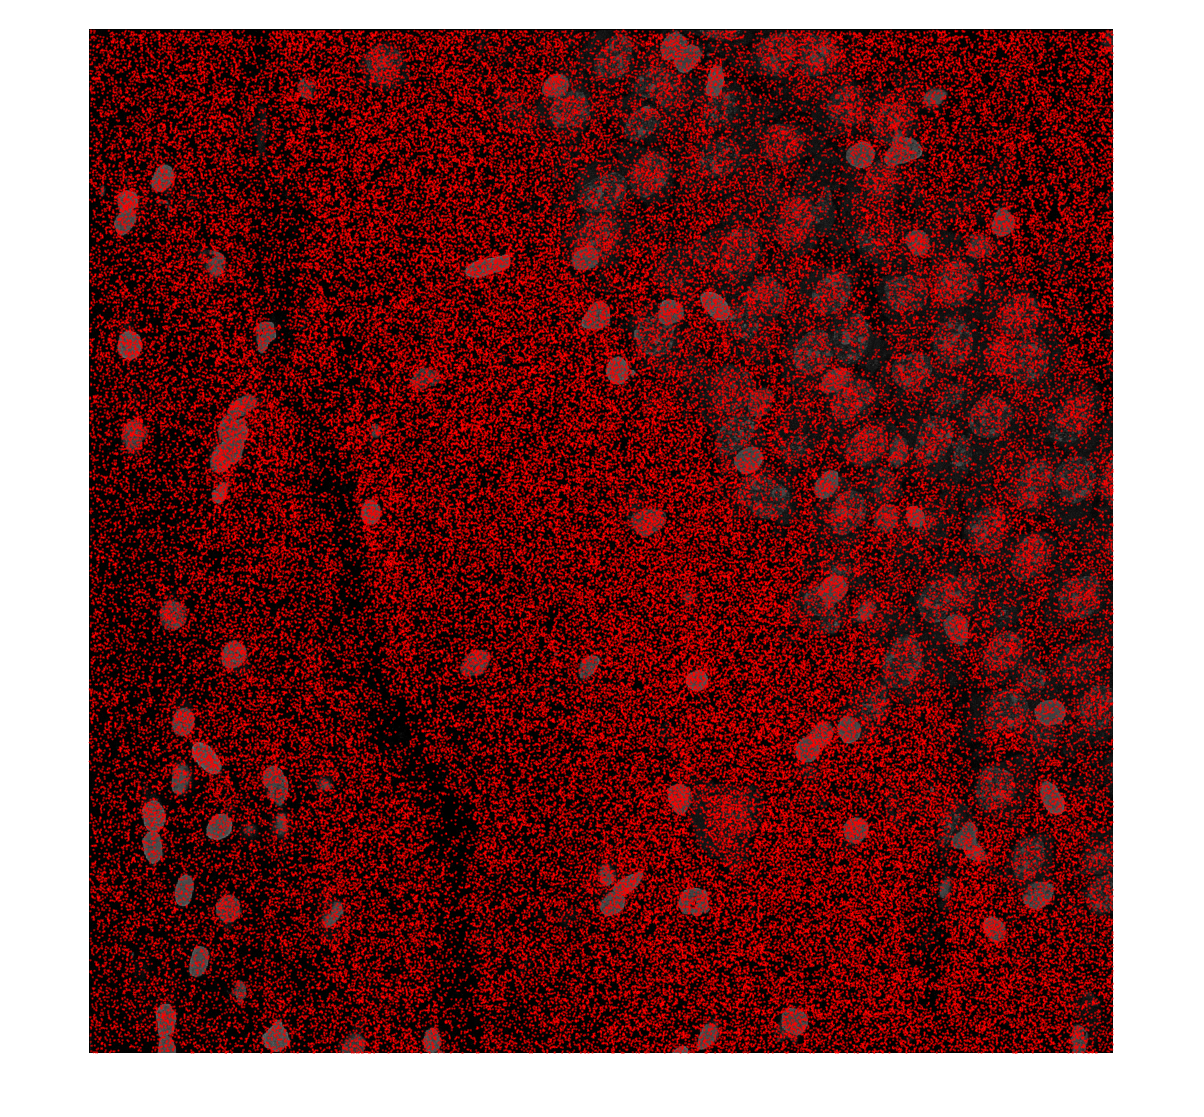

img = new_LoadMultipageTiff(fullfile('F:/2020-09-14-mAD/AD_mouse9735/output/max/pi/tile_2.tif'), 'uint8', 'uint8', false);
% img = max(sdata.registeredImages(:,:,:,:,1), [], 4);
img = max(img, [], 3);
% img = zeros(size(img), 'uint8');
plot_centroids(tile_goodSpots, img, 3)

input_path = 'F:/2020-09-14-mAD/AD_mouse9735/';
[ geneToSeq, seqToGene ] = new_LoadCodebook( input_path, 5, true );
gene = 'CPLX2';
seq = geneToSeq(gene);
good_points = ismember(tile_goodReads, seq);
good_points = tile_goodSpots(good_points, :);

size(good_points, 1)

imshow(img)
hold on
plot(good_points(:,1), good_points(:,2), '.', "Color", 'red', "MarkerSize", 3)
hold off

[C,ia,ic] = unique(tile_goodReads);
a_counts = accumarray(ic,1);
value_counts = table(C, a_counts);
value_counts = sortrows(value_counts, 'a_counts', 'descend');
genes = cellfun(@(x) seqToGene(x), value_counts.C, 'UniformOutput', false);
value_counts.genes = genes;

saveAS = true;
curr_out_path = fullfile("F:/2020-09-14-mAD/AD_mouse9723/output/rd1_dots/allSpots_figures/")

zs = unique(tile_allSpots(:,3)); 

img = max(sdata.registeredImages(:,:,:,:,8), [], 4);

for z=1:numel(zs)

    good_points = tile_allSpots(tile_allSpots(:, 3) == zs(z), :);
    
    npoints = size(good_points, 1);
    
    figure
    imshow(img(:,:,zs(z)))
    hold on
    plot(good_points(:,1), good_points(:,2), '.', "Color", 'red', "MarkerSize", 3)
    title(z)
    hold off
    
    if saveAS
        fig_name = fullfile(curr_out_path, sprintf("%d_%d.png", z, npoints));
        saveas(gcf, fig_name)
    end
        
end


## Reads ex

% load file
input_path = 'F:/2020-09-14-mAD/AD_mouse9723/';
sdata = new_STARMapDataset(input_path, 'useGPU', false);
sdata = sdata.LoadCodebook('remove_index', 5);

endBases = ['C', 'T']
filtBases = sdata.basecsMat;
correctSeqs = zeros(size(filtBases,1), 2); % count sequences that are of correct form

cs_front = filtBases(:, 1:4);
cs_back = filtBases(:, 5:8);

bases_front = new_DecodeCS(cs_front, endBases(1));
bases_back = new_DecodeCS(cs_back, endBases(2));

for i=1:numel(bases_front)
    currSeq = bases_front{i};
    if currSeq(1) == endBases(1) && currSeq(end) == endBases(1)
        correctSeqs(i, 1) = 1;
    end
end

for i=1:numel(bases_back)
    currSeq = bases_back{i};
    if currSeq(1) == endBases(2) && currSeq(end) == endBases(2)
        correctSeqs(i, 2) = 1;
    end
end

correctSeqs = correctSeqs(:,1) .* correctSeqs(:,2);

fprintf('Filtration Statistics:\n');
% fprintf(obj.log, 'Filtration Statistics:\n');
score_1 = sum(correctSeqs)/size(filtBases,1);
s = sprintf('%f [%d / %d] percent of good reads match barcode pattern %sN..N%s - %sN..N%s\n',...
    sum(correctSeqs)/size(filtBases,1),...
    sum(correctSeqs),...
    size(filtBases,1),...
    endBases(1),...
    endBases(1),...
    endBases(2),...
    endBases(2));
fprintf(s);
% fprintf(obj.log, s);
    
% filter reads based on codebook
Nreads = numel(sdata.allReads);
inCodebook = zeros(Nreads, 1);
codebookSeqs = sdata.barcodeSeqs;

for s=1:Nreads
    str = sdata.allReads{s};
    if ismember(str, codebookSeqs)         
        inCodebook(s) = 1;
    else
        inCodebook(s) = 0;
    end
end

% sum(inCodebook)

readsToKeep = inCodebook==1;
sdata.goodSpots = sdata.allSpots(readsToKeep,:);
sdata.goodReads = sdata.allReads(readsToKeep);
sdata.goodScores = sdata.allScores(readsToKeep,:);

if showPlots
    figure(1);
    errorbar(mean(sdata.goodScores), std(sdata.goodScores),'ko-'); 
    xlim([0 obj.Nround+1]); 
    xlabel('Round'); ylabel('Average qual score');
end

score_2 = sum(readsToKeep)/Nreads;
s = sprintf('%f [%d / %d] percent of good reads are in codebook\n',...
    sum(readsToKeep)/Nreads,...
    sum(readsToKeep),...
    Nreads);
fprintf(s);
% fprintf(obj.log, s);

score_3 = sum(readsToKeep)/sum(correctSeqs);
s = sprintf('%f [%d / %d] percent of form matched reads are in codebook\n',...
    sum(readsToKeep)/sum(correctSeqs),...
    sum(readsToKeep), ...
    sum(correctSeqs));            
fprintf(s);
%fprintf(obj.log, s);

%obj.FilterScores = [score_1 score_2 score_3]; 
    
    

    fname = fullfile(input_path, 'genes.csv');
    f = readmatrix(fname, 'OutputType', 'string', "Delimiter", ',');
    if true
        f(:,2) = reverse(f(:,2));
    end

    for i=1:size(f, 1)
        f(i,2) = new_EncodeBases(f(i,2));
    end
    remove_index = 5;
    flip = true;
    if ~isempty(remove_index)
        f(:,2) = eraseBetween(f(:,2), remove_index, remove_index);
        if flip
            front = extractAfter(f(:,2), remove_index-1);
              back = extractBefore(f(:,2), remove_index);
              f(:,2) = front + back;
        end
    end